## Kirchhoff's circuit laws

Simple linear circuits can be analyzed using Ohm's law and Kirchoff's circuit laws. Matrices provide a natural framework: they can concisely capture the many linear equations that model the circuit network.

### Kirchhoff's current law

The sum of all currents flowing into a node equals the sum of currents flowing out of the node.

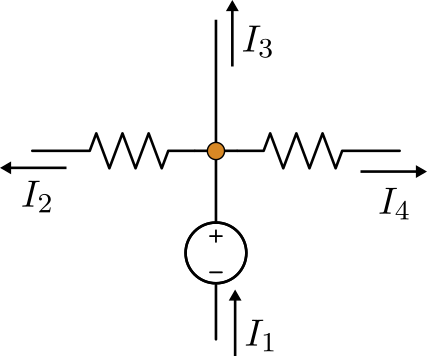

*At this node, Kirchhoff's current law implies that *$I_1 = I_2 + I_3 + I_4 $.

### Kirchhoff's voltage law

The sum of voltages around a closed loop of a circuit is zero. Mathematically:

    
$$\sum_{k} V_k = 0$$


where $V_k$ is the potential difference across the $k^{th}$ branch of the circuit. Using Ohm's law, the potential drop across each resistor is $V = IR$.

 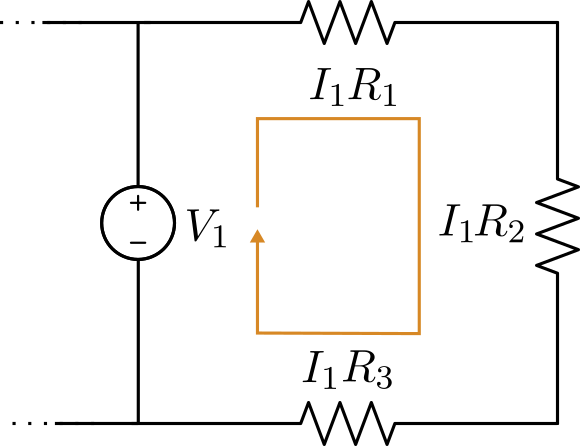

*The potential drop across the resistors in this closed loop must equal the potential generated by the voltage source: *$V_1 - I_1 R_1 - I_1 R_2 - I_1 R_3 = 0$.

## Matrix representation of a circuit

In this section, the pictured linear circuit will be analyzed using Kirchhoff's laws, written in matrix form.

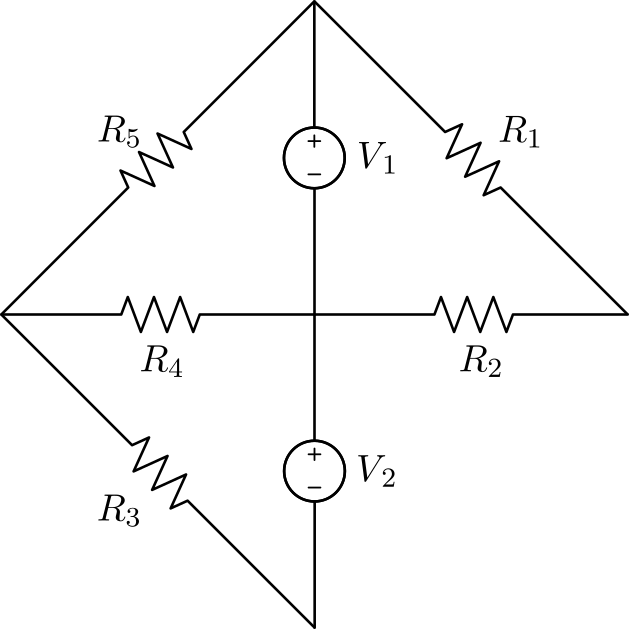

*The circuit to be analyzed*

### Derivation of the equations

Before writing the equations, it is useful to define current paths through the circuit. This provides a framework for applying Kirchhoff's laws. Note that the current paths are arbitrary, as current flowing in the opposite direction will simply be represented as a negative value. However, the chosen reference directions determine the correct form of Kirchhoff's laws.

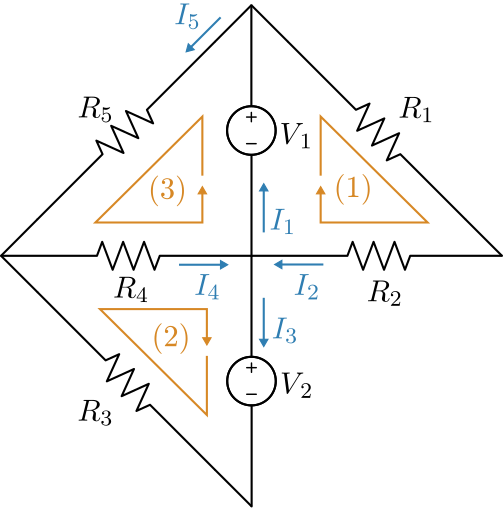

*In this diagram, three closed loops of the circuit are labeled (1), (2), and (3). The distinct currents in the circuit are also labeled.*

Applying **Kirchhoff's current law** to the central node yields:

    
$$I_2 + I_4 = I_1 + I_3$$


Applying **Kirchhoff's voltage law **to the three loops adds three additional equations:

    
$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


At this point, we have 5 unknown currents, but only four equations. To complete the representation, another application of the Kirchhoff's current law is required. For the top node:

    
$$I_1 = I_2 + I_5$$


### Derivation of the matrix form of the equations

To write these equations in matrix form $\mathbf{AI} = \mathbf{b}$, define the solution vector 

    
$$\mathbf{I} = \left[ \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right]$$


Moving all variable terms to the LHS and constant terms to the RHS implies:

     
$$\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$$


So the matrix form of the system is

    
$$\left[ 
\begin{array}{ccccc} 
0 & R_1 + R_2 & 0 & 0 & 0 
\\
0 & 0 & R_3 & R_4 & 0
\\
0 & 0 & 0 & R_4 & R_5
\\
1 & -1 & 1 & -1 & 0
\\
1 & -1 & 0 & 0 & -1
\end{array}
\right]
\left[ \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right]
=
\left[ \matrix{ V_1 \cr -V_2 \cr V_1 \cr 0 \cr 0 } \right]$$


### Solutions to the matrix system

**A specific solution. **Suppose that the resistors and voltage sources have values:

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 100 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 1 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 1.5 \ \text{V}
\end{array}$$


What are the currents through the circuit?

% Solve for the current by defining the matrix A,the RHS vector b, and
% then applying the backslash operator (\)
A = [0 110  0   0   0; 
     0   0 10 1e3   0;
     0   0  0 1e3 330;
     1  -1  1  -1   0;
     1  -1  0   0  -1]

A =            0         110           0           0           0
           0           0          10        1000           0
           0           0           0        1000         330
           1          -1           1          -1           0
           1          -1           0           0          -1


b = [1.5 -1.5 1.5 0 0]'

b =     1.5000
   -1.5000
    1.5000
         0
         0



I = A\b

I =     0.0224
    0.0136
   -0.0102
   -0.0014
    0.0088


**General solution.** You can also use symbolic math to find solutions to this circuit for arbitrary resitances and voltages. 

% Define symbolic variables for the resistances and voltages
syms R_1 R_2 R_3 R_4 R_5 V_1 V_2

% Solve for the current by defining the matrix A,the RHS vector b, and
% then applying the backslash operator (\)
A = [0 R_1+R_2   0   0   0; 
     0       0 R_3 R_4   0;
     0       0  0  R_4 R_5;
     1      -1  1   -1   0;
     1      -1  0    0  -1]

$$A = \left(\begin{array}{ccccc} 0 & R_{1}+R_{2} & 0 & 0 & 0\\ 0 & 0 & R_{3} & R_{4} & 0\\ 0 & 0 & 0 & R_{4} & R_{5}\\ 1 & -1 & 1 & -1 & 0\\ 1 & -1 & 0 & 0 & -1 \end{array}\right)$$

b = [V_1; -V_2; V_1; 0; 0]

$$b = \left(\begin{array}{c} V_{1}\\ -V_{2}\\ V_{1}\\ 0\\ 0 \end{array}\right)$$


I = A\b

$$I = \begin{array}{l} \left(\begin{array}{c} \frac{R_{1}\,R_{3}\,V_{1}+R_{1}\,R_{4}\,V_{1}+R_{2}\,R_{3}\,V_{1}+R_{1}\,R_{4}\,V_{2}+R_{2}\,R_{4}\,V_{1}+R_{2}\,R_{4}\,V_{2}+R_{3}\,R_{4}\,V_{1}+R_{3}\,R_{5}\,V_{1}+R_{4}\,R_{5}\,V_{1}}{\left(R_{1}+R_{2}\right)\,\sigma_{1}}\\ \frac{V_{1}}{R_{1}+R_{2}}\\ -\frac{R_{4}\,V_{1}+R_{4}\,V_{2}+R_{5}\,V_{2}}{\sigma_{1}}\\ \frac{R_{3}\,V_{1}-R_{5}\,V_{2}}{\sigma_{1}}\\ \frac{R_{3}\,V_{1}+R_{4}\,V_{1}+R_{4}\,V_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{3}\,R_{4}+R_{3}\,R_{5}+R_{4}\,R_{5} \end{array}$$

You can use the symbolic solution to generate a MATLAB anonymous function that can be evaluated for a specific solution:

Ifunc = matlabFunction(I)

Ifunc = function_handle with value:
    @(R_1,R_2,R_3,R_4,R_5,V_1,V_2)[(R_1.*R_3.*V_1+R_1.*R_4.*V_1+R_2.*R_3.*V_1+R_1.*R_4.*V_2+R_2.*R_4.*V_1+R_2.*R_4.*V_2+R_3.*R_4.*V_1+R_3.*R_5.*V_1+R_4.*R_5.*V_1)./((R_1+R_2).*(R_3.*R_4+R_3.*R_5+R_4.*R_5));V_1./(R_1+R_2);-(R_4.*V_1+R_4.*V_2+R_5.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5);(R_3.*V_1-R_5.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5);(R_3.*V_1+R_4.*V_1+R_4.*V_2)./(R_3.*R_4+R_3.*R_5+R_4.*R_5)]


Ifunc(10,100,10,1e3,330,1.5,1.5)

ans =    0.022418769695204
   0.013636363636364
  -0.010180600058258
  -0.001398193999417
   0.008782406058841
